clc; 
clear; 
close all; 
% Parameters 
Am = 1;       
fm = 100;     
Ac = 5;       
fc = 1000;    
fs = 20*fc;   
kp = pi/2;    
% Message Amplitude (V) 
% Message Frequency (Hz) 
% Carrier Amplitude (V) 
% Carrier Frequency (Hz) 
% Sampling Frequency (Hz) 
% Phase Sensitivity (rad/V) 
% Time Vector 
t = 0:1/fs:4/fm; 
% Message Signal 
m = Am*sin(2*pi*fm*t); 
% PM Signal 
pm = Ac*cos(2*pi*fc*t + kp*m); 
% Phase Deviation 
beta = kp*Am; 
% FFT 
N = length(pm); 
f = linspace(-fs/2,fs/2,N); 
PM_FFT = abs(fftshift(fft(pm)))/N; 
% Power Spectral Density 
PSD = (abs(fftshift(fft(pm))).^2)/(N*fs); 
% Approximate Bandwidth 
BW = 2*(beta+1)*fm; 
fprintf('Phase Deviation = %.2f radians\n',beta); 

Phase Deviation = 1.57 radians


fprintf('Estimated Bandwidth = %.2f Hz\n',BW); 

Estimated Bandwidth = 514.16 Hz


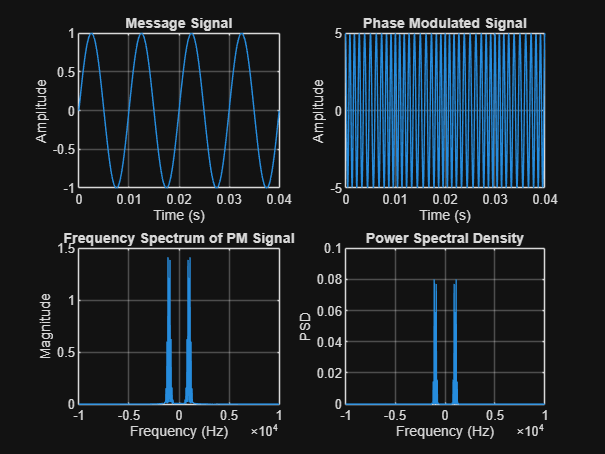

% Plotting 
figure('Name','PSD Analysis of PM Signal','NumberTitle','off'); 
subplot(2,2,1); 
plot(t,m); 
title('Message Signal'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
grid on; 
subplot(2,2,2); 
plot(t,pm); 
title('Phase Modulated Signal'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
grid on; 
subplot(2,2,3); 
plot(f,PM_FFT); 
title('Frequency Spectrum of PM Signal'); 
xlabel('Frequency (Hz)'); 
ylabel('Magnitude'); 
grid on; 
subplot(2,2,4); 
plot(f,PSD); 
title('Power Spectral Density'); 
xlabel('Frequency (Hz)'); 
ylabel('PSD'); 
grid on;